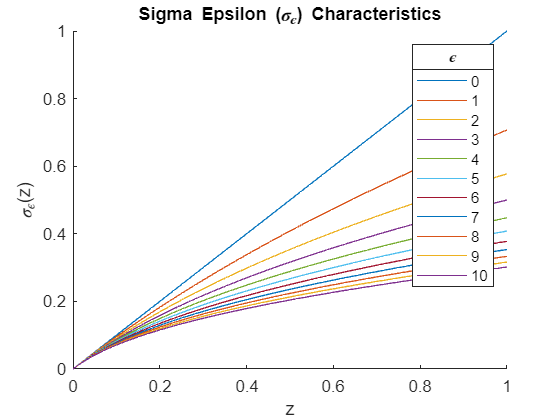

% Sigma Epsilon Characteristics

cla;
title("Sigma Epsilon (\sigma_{\epsilon}) Characteristics")
z = linspace(0, 1, 100)';
for i = 0:10
    hold on;
    plot(z, sigmaEpsilon(z, i));
end
legend(["0", "1", "2", "3", "4", "5", "6", "7", "8", "9", "10"]);
title(legend, "\epsilon");
xlabel("z");
ylabel("\sigma_{\epsilon}(z)")
hold off;

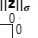

% Sigma Norm Characteristics

cla;
title("Sigma Norm (||z||_{\sigma} Characteristics")
z = linspace(0, 1, 100)';
for i = 1:10
    hold on;
    plot(z, sigmaNorm(z, i));
end
legend(["1", "2", "3", "4", "5", "6", "7", "8", "9", "10"]);
title(legend, "\epsilon");
xlabel("z");
ylabel("||z||_{\sigma}");
hold off;

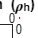

% Bump Function Characteristics

cla;
title("Bump Function (\rho_h) Characteristics");
z = linspace(0, 1, 100)';
for i = 0:0.1:1
    hold on;
    plot(z, bumpFunction(z, i));
end
legend(["0", "0.1", "0.2", "0.3", "0.4", "0.5", "0.6", "0.7", "0.8", "0.9", "1.0"]);
title(legend, "h")
xlabel("z");
ylabel("{\rho}_{h}");
hold off;

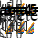

% Phi Characteristics

cla;
sgtitle("\phi characteristics", "FontName", "New York Times")
subplot(2, 3, 1);
z = linspace(0, 1, 100)';
for i = 1:10
    hold on;
    plot(z, phi(z, i, 0.5*i));
end
set(legend,'visible','off')
ylabel("\phi(z)");
xlabel("z");
title("b/a = 0.5")

subplot(2, 3, 2);
z = linspace(0, 1, 100)';
for i = 1:10
    hold on;
    plot(z, phi(z, i, 1*i));
end
set(legend,'visible','off')
ylabel("\phi(z)");
xlabel("z");
title("b/a = 1")

subplot(2, 3, 3);
z = linspace(0, 1, 100)';
for i = 1:10
    hold on;
    plot(z, phi(z, i, 2*i));
end
set(legend,'visible','off')
ylabel("\phi(z)");
xlabel("z");
title("b/a = 2")

subplot(2, 3, 4);
z = linspace(0, 1, 100)';
for i = 1:10
    hold on;
    plot(z, phi(z, i, 4*i));
end
set(legend,'visible','off')
ylabel("\phi(z)");
xlabel("z");
title("b/a = 4")

subplot(2, 3, 5);
z = linspace(0, 1, 100)';
for i = 1:10
    hold on;
    plot(z, phi(z, i, 5.5*i));
end
set(legend,'visible','off')
ylabel("\phi(z)");
xlabel("z");
title("b/a = 5.5")

subplot(2, 3, 6);
z = linspace(0, 1, 100)';
for i = 1:10
    hold on;
    plot(z, phi(z, i, 7*i));
end
set(legend,'visible','off')
ylabel("\phi(z)");
xlabel("z");
title("b/a = 7")

hold off;

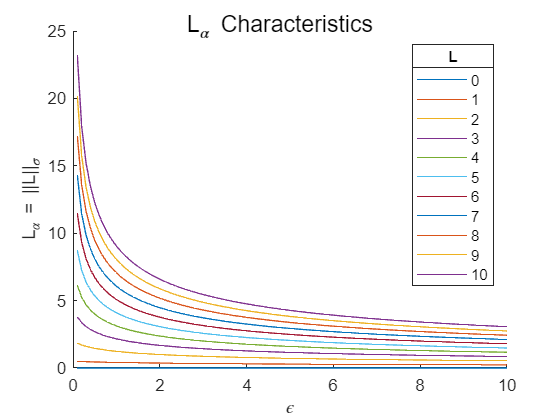

% Lattice Params 
epsilon = 1;
r = 1;
d = 0.7;
kappa = r/d;

% transformed params
r_alpha = sigmaNorm(r, epsilon);
d_alpha = sigmaNorm(d, epsilon);

% Characteristics
figure;
hold on;
sgtitle("L_{\alpha} Characteristics");
z = linspace(0.1, 10, 100)';
for c = 0:10
    plot(z, sigmaNorm(c, z));
end
legend(["0", "1", "2", "3", "4", "5", "6", "7", "8", "9", "10"]);
% L is some metric for length, such as r or d
title(legend, "L");
xlabel("\epsilon");
ylabel("L_{\alpha} = ||L||_{\sigma}");

hold off;

Now we are equipped to calculate the appropriate force between two boids at a mutual distance of d. This is given by the phi_alpha function. Here, we analyse the same.

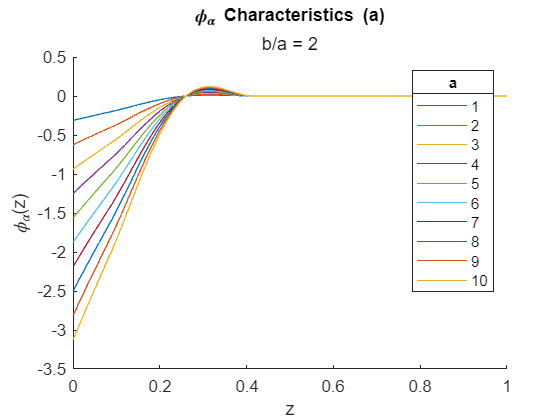

% Phi Alpha Characteristics
figure();
cla;
title("\phi_{\alpha} Characteristics (a)")
subtitle("b/a = 2")
z = linspace(0, 1, 100)';
for i = 1:10
    hold on;
    plot(z, phi_alpha(z, r_alpha, d_alpha, i, 2*i));
end
legend(["1", "2", "3", "4", "5", "6", "7", "8", "9", "10"]);
title(legend, "a");
xlabel("z");
ylabel("\phi_{\alpha}(z)");
hold off;

Increasing "a" leads to an increase in the slope closer to 0. This implies a stronger repulsive force the closer two boids are.

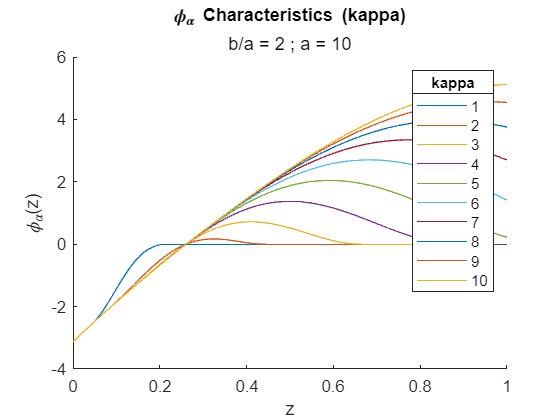


figure();
cla;
title("\phi_{\alpha} Characteristics (kappa)")
subtitle("b/a = 2 ; a = 10")
z = linspace(0, 1, 100)';
for i = 1:10
    hold on;
    kappa = i;
    plot(z, phi_alpha(z, kappa*d_alpha, d_alpha, 10, 20));
end
legend(["1", "2", "3", "4", "5", "6", "7", "8", "9", "10"]);
title(legend, "kappa");
xlabel("z");
ylabel("\phi_{\alpha}(z)");
hold off;

d_alpha

d_alpha = 0.2207

The increasing value of kappa causes an increase in the overshoot of phi_alpha past d_alpha, as it is equivalent to an increase in the interaction range of two boids. Recall that two boids can sense each other when they are within a distance r_alpha of each other. Initially d and r, note that the parameters were transformed. 

Thus for a "good" potential, where we might want strong repulsion for nearby boids and a relatively weaker attraction for boids that can sense each other but are not at an optimal distance, we may prefer a high value of "a", and a medium  value of kappa. We will look into quantifying these values later when we design a controller. 

Integrating the potentials we've generated above from d_alpha to x gives us the force a boid will exert on a neighbouring boid at a distance x away. 

This step is unnecessary as far as implementation goes, but could prove handy in a proof regarding stability. 

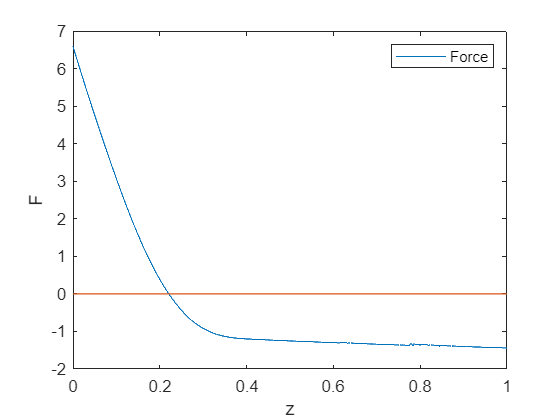

% Finding the POTENTIAL CURVE
xmax = 1;
n = 10000;

cla;
title("Potential Characteristics");
subtitle("");
a = 100;
b = 2*a;
f = @(z, r_alpha, d_alpha, a, b) phi_alpha(z, r_alpha, d_alpha, a, b);

z = linspace(0, xmax, n)';
F = zeros(n,1);
for i = 1:n
    F(i) = integral(@(z) f(z, r_alpha, d_alpha, a, b), d_alpha, xmax*i/n);
end
plot(z, F);
hold on;
plot([0,xmax], [0,0]);
legend("Force");
xlabel("z");
ylabel("F");

A matlab numerical integration error: the force generated is negative for all values past d_alpha, whereas we expected a cutoff at r_alpha. Perhaps misuse of the integral function of matlab. 

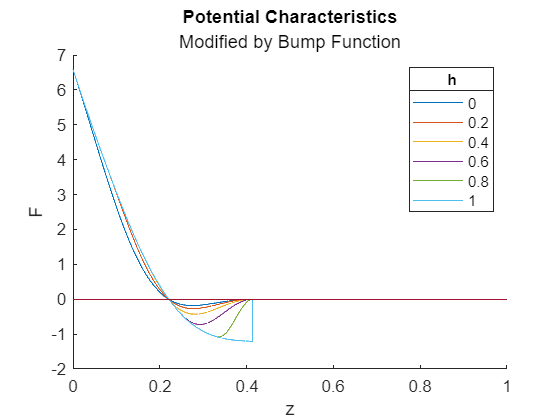

figure();

title("Potential Characteristics");
subtitle("Modified by Bump Function");
a = 100;
b = 2*a;
f = @(z, r_alpha, d_alpha, a, b) phi_alpha(z, r_alpha, d_alpha, a, b);

z = linspace(0, xmax, n)';
F = zeros(n,1);
hold on;
for j = 0:0.2:1
    for i = 1:n
        F(i) = (bumpFunction(z(i)/r_alpha, j)) * integral(@(z) f(z, r_alpha, d_alpha, a, b), d_alpha, xmax*i/n);
    end
    plot(z, F);
end
plot([0,xmax], [0,0]);
legend(["0", "0.2", "0.4", "0.6", "0.8", "1"]);
title(legend, "h");
xlabel("z");
ylabel("F");

A simple functional fix for now: we mulitply the force we've previously generated with (1 - bump function) such that the bump function cuts off at r_alpha. The graph depicts the function for different values of h.

function out = sigmaEpsilon(z, epsilon)
    out = (z) ./ sqrt(1 + epsilon*(vecnorm((z), 2, 2)));
end

function out = phi(z, a, b) 
    % merely scaling and shifting the sigmaEpsilon function
    c = abs(a-b)/sqrt(4*a*b);
    out = 0.5 * ((a+b) * sigmaEpsilon(z+c, 1) + (a-b));
end

function out = phi_alpha(z, r_alpha, d_alpha, a, b)
    out = bumpFunction(z/r_alpha, 0.2) .* phi(z-d_alpha, a, b);
end

function rho = bumpFunction(z, h)
    rho = zeros(size(z));
    rho(z >= 0 & z < h) = 1;
    rho(z >= h & z <= 1) = (1/2) * (1 + cos(pi * ((z(z >= h & z <= 1) - h)/(1 - h))));
end

function out = sigmaNorm(z, epsilon)
    c = (sqrt(1 + epsilon * vecnorm(z, 2, 2).^2) - 1);
    out = (1 ./ epsilon) .* c;
end